# **Third Optimal Control Project**

# **Design of a Finite-Time LQT Controller with Integral Action for a Mass-Spring-Damper System**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com


clear all;
close all;
clc

m1 = 1;
m2 = 1;
c1 = 1;
c2 = 1;
k1 = 1;
k2 = 1;

A = [0 1 0 0;
    -(k1+k2)/m1  -(c2+c1)/m1  k2/m1  c2/m1;
    0 0 0 1;
    k2/m2  c2/m2  -k2/m2  -c2/m2];

B = [0; 0; 0; 1/m2];
C = [1 0 0 0];

Q = 50;
R = 1;
Qf = Q;
T = 10;

P_T = C'*Qf*C;
P0_flat = P_T(:);
tspan = linspace(T, 0, 100); 

[t_rev, P_sol] = ode45(@(t, P) riccatiODE(t, P, A, B, C, Q, R), tspan, P0_flat);

t_fwd = flipud(t_rev);
P_fwd = flipud(P_sol);

r_func = @(t) 10;
n = size(A,1);
P_interp_fun = @(t) reshape(interp1(t_fwd, P_fwd, t), n, n);
eta_T = C'*Qf*r_func(T);

[t_rev, eta_sol] = ode45(@(t, eta) etaODE(t, eta, A, B, C, Q, R, P_interp_fun, r_func), tspan, eta_T);

t_fwd_eta = flipud(t_rev);
eta_fwd = flipud(eta_sol);

x0 = zeros(4,1);

[t_sim, x_sim] = ode45(@(t, x) ...
    controlledSystem(t, x, A, B, R, P_interp_fun, t_fwd_eta, eta_fwd), ...
    [0 T], x0);

y_sim = x_sim * C';
r = 10*ones(size(t_sim));

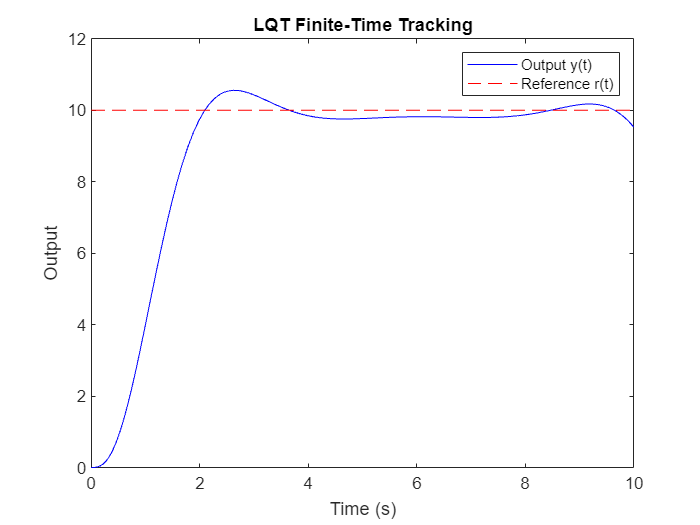

figure;
plot(t_sim, y_sim, 'b', t_sim, r, 'r--');
legend('Output y(t)', 'Reference r(t)');
xlabel('Time (s)');
ylabel('Output');
title('LQT Finite-Time Tracking');